% find out name of the rat
thisFolder = pwd;
thisFolderSplitted = strsplit(thisFolder, filesep);
NameIndex =  find(strcmp(thisFolderSplitted, 'ANMs'))+1;
ratName = thisFolderSplitted{NameIndex};


disp(['this rat is: ', ratName])

this rat is: Pepper


savename1 = ['BClassArray_' upper(ratName)];

disp(savename1)

BClassArray_PEPPER



% Read folders
rootFolder = pwd;
files = dir(rootFolder);
dirFlags = [files.isdir];
subFolders = files(dirFlags);
subFolderNames = {subFolders(3:end).name};
dataFolderNames = {};
for k =1:length(subFolderNames)
    if ~isempty(str2num(subFolderNames{k}))
        dataFolderNames = [dataFolderNames  subFolderNames{k}];
        fprintf('Subfolder #%d = %s \n', k,  subFolderNames{k})
    end
end

Subfolder #1 = 20221223 
Subfolder #2 = 20221224 
Subfolder #3 = 20221226 
Subfolder #4 = 20221227 
Subfolder #5 = 20221228 
Subfolder #6 = 20221229 
Subfolder #7 = 20221230 
Subfolder #8 = 20221231 
Subfolder #9 = 20230102 
Subfolder #10 = 20230103 
Subfolder #11 = 20230104 
Subfolder #12 = 20230105 
Subfolder #13 = 20230106 
Subfolder #14 = 20230107 
Subfolder #15 = 20230109 
Subfolder #16 = 20230110 
Subfolder #17 = 20230111 
Subfolder #18 = 20230112 


dataFolderNames'

ans = 18×1 cell 数组
    {'20221223'}
    {'20221224'}
    {'20221226'}
    {'20221227'}
    {'20221228'}
    {'20221229'}
    {'20221230'}
    {'20221231'}
    {'20230102'}
    {'20230103'}
    {'20230104'}
    {'20230105'}
    {'20230106'}
    {'20230107'}
    {'20230109'}
    {'20230110'}
    {'20230111'}
    {'20230112'}


Behavior.MED.DisplayMEDs

this rat is: Pepper
Subfolder #1 = 20221223 
Subfolder #2 = 20221224 
Subfolder #3 = 20221226 
Subfolder #4 = 20221227 
Subfolder #5 = 20221228 
Subfolder #6 = 20221229 
Subfolder #7 = 20221230 
Subfolder #8 = 20221231 
Subfolder #9 = 20230102 
Subfolder #10 = 20230103 
Subfolder #11 = 20230104 
Subfolder #12 = 20230105 
Subfolder #13 = 20230106 
Subfolder #14 = 20230107 
Subfolder #15 = 20230109 
Subfolder #16 = 20230110 
Subfolder #17 = 20230111 
Subfolder #18 = 20230112 
~~~~~~~~~~~~~~~~~~~~~~~~~~
~~~~~~~~~~~~~~~~~~~~~~~~~~
20221223 | SRT_Step8_FR1_SingleFPBpod | Experiment: 
20221224 | SRT_Step8_FR1_SingleFPBpod | Experiment: 
20221226 | SRT_Step8_FR1_SingleFPBpod | Experiment: Saline
20221227 | SRT_Step8_FR1_SingleFPBpod | Experiment: Saline
20221228 | SRT_Step8_FR1_SingleFPBpod | Experiment: DCZ
20221229 | SRT_Step8_FR1_SingleFPBpod | Experiment: Saline
20221230 | SRT_Step8_FR1_SingleFPBpod | Experiment: Saline
20221231 | SRT_Step8_FR1_SingleFPBpod | Experiment: DCZ
20230102 | SR

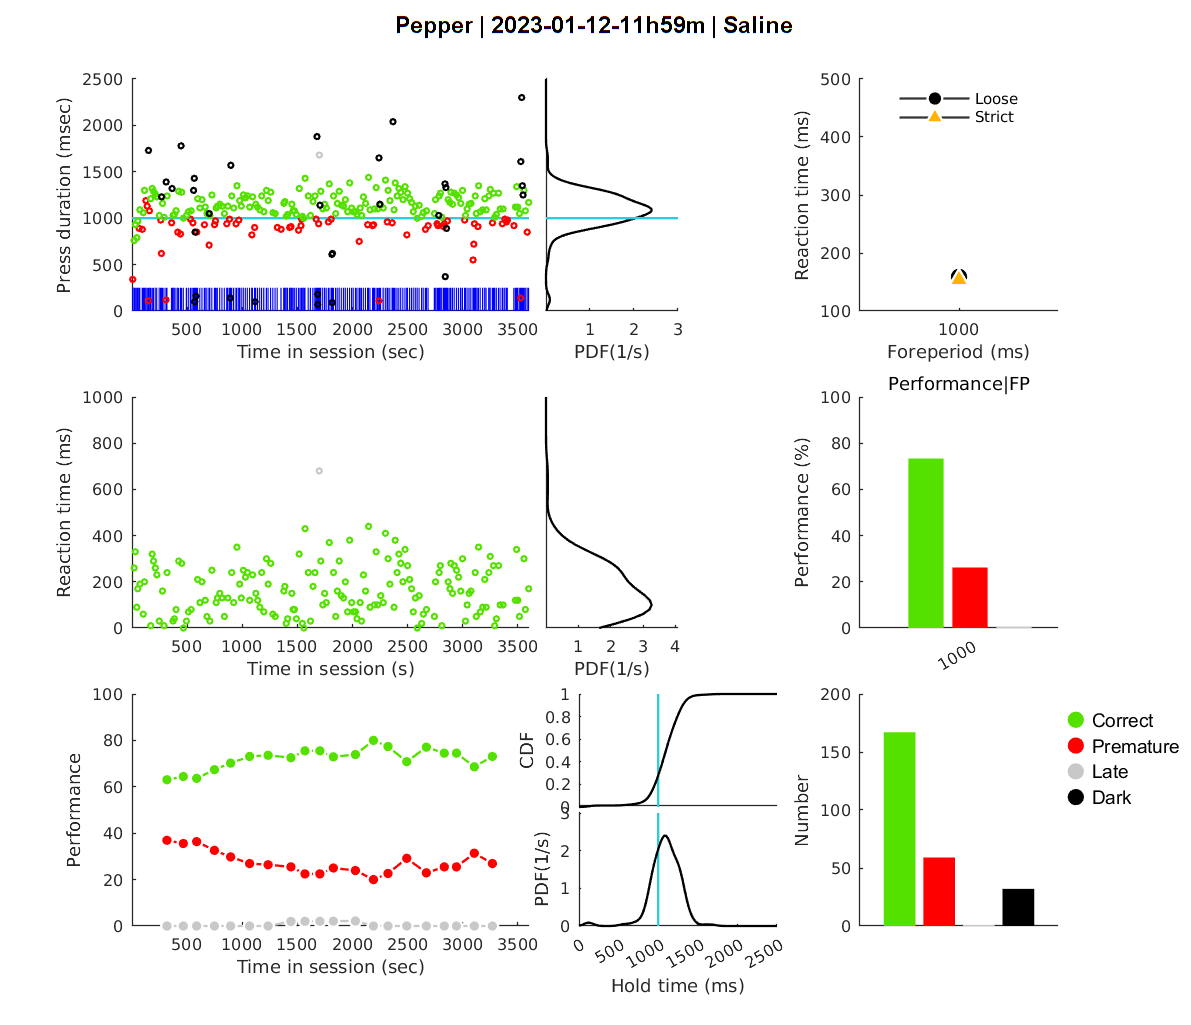

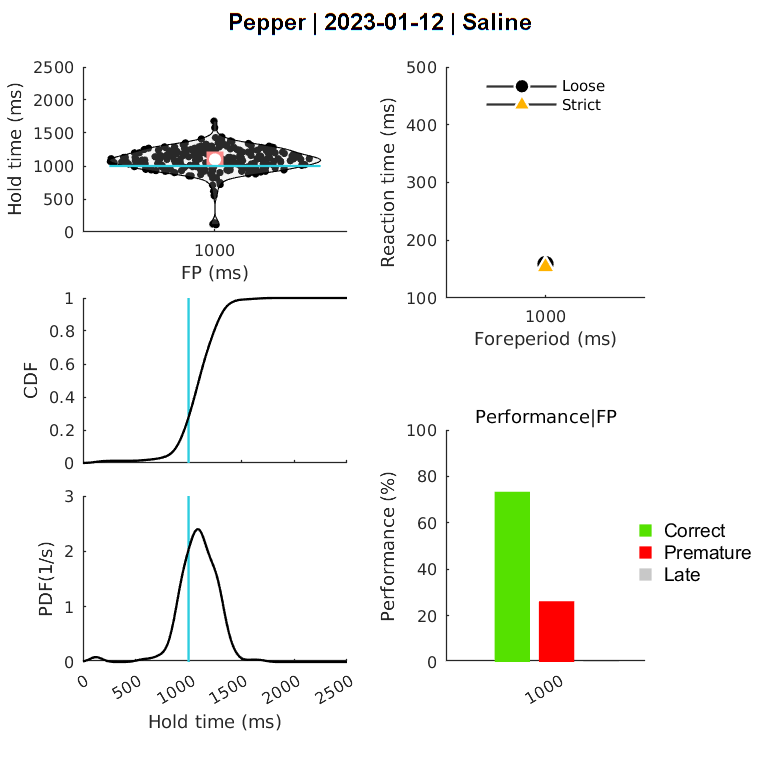

AllSessions = [
    % date          treatment   dose
    {'20221223'}    'Saline'    0
    {'20221224'}    'Saline'    0
    {'20221226'}    'Saline'    0
    {'20221227'}    'Saline'    0
    {'20221228'}    'DCZ'       1
    {'20221229'}    'Saline'    0
    {'20221230'}    'Saline'    0
    {'20221231'}    'DCZ'       1
    {'20230102'}    'Saline'    0
    {'20230103'}    'Saline'    0
    {'20230104'}    'DCZ'       1
    {'20230105'}    'Saline'    0
    {'20230106'}    'Saline'    0
    {'20230107'}    'DCZ'       1
    {'20230109'}    'Saline'    0
    {'20230110'}    'Saline'    0
    {'20230111'}    'DCZ'       1
    {'20230112'}    'Saline'    0];

BClassArray = {};

bAllFPsBpod=struct('Metadata',[],'SessionName',[],'PressTime',[],'ReleaseTime', [],...
    'Correct',[],'Premature',[],'Late',[],'Dark', [],...
    'ReactionTime',[],'TimeTone',[],'IndToneLate',[], 'FPs', []);

for i=1:length(AllSessions)
    cd(fullfile(thisFolder, AllSessions{i, 1}))
    iMED = dir(['*' ratName '.txt']);
    [~, bc]=Behavior.MED.track_training(iMED.name);
    close all;

    bc.Treatment = AllSessions{i, 2};
    bc.Dose      = AllSessions{i, 3};
    bc.MixedFP = 1000;

    bc.Plot()
    bc.PlotDistribution()
    bc.Print()
    BClassArray{i}= bc;
end


cd(thisFolder)
save (savename1, 'BClassArray')

% find out name of the rat
thisFolder = pwd;
thisFolderSplitted = strsplit(thisFolder, filesep);
NameIndex =  find(strcmp(thisFolderSplitted, 'ANMs'))+1;
ratName = thisFolderSplitted{NameIndex};


disp(['this rat is: ', ratName])

this rat is: Pepper


savename1 = ['BClassArray_' upper(ratName)];
disp(savename1)

BClassArray_PEPPER


close all
load(savename1)
obj=Behavior.SRT.BehaviorGroupClass(BClassArray); % this is the group obj. Note that I am using package mode to organize these data

obj.SessionControl = {'20221227','20221230','20230103','20230106','20230110'};
obj.SessionChemo   = {'20221228','20221231','20230104','20230107','20230111'};
obj.MixedFP = 1000;

obj= obj.CalRTChemo;
obj.PlotPerformance;

xlevel = 11.5000

The arrow function was removed from EEGLAB
because of lack of compatibility with Matlab 2019
An updated version of the function is available at
https://www.mathworks.com/matlabcentral/fileexchange/278-arrow
The arrow function was removed from EEGLAB
because of lack of compatibility with Matlab 2019
An updated version of the function is available at
https://www.mathworks.com/matlabcentral/fileexchange/278-arrow
The arrow function was removed from EEGLAB
because of lack of compatibility with Matlab 2019
An updated version of the function is available at
https://www.mathworks.com/matlabcentral/fileexchange/278-arrow
The arrow function was removed from EEGLAB
because of lack of compatibility with Matlab 2019
An updated version of the function is available at
https://www.mathworks.com/matlabcentral/fileexchange/278-arrow
The arrow function was removed from EEGLAB
because of lack of compatibility with Matlab 2019
An updated version of the function is available at
https://www.mathworks.com/ma

obj.PlotChemoEffect;

htl1 =   Text (Control 20221227|20221230|20230103|20230106|20230110|) - 属性:

                 String: 'Control 20221227|20221230|20230103|20230106|20230110|'
               FontSize: 6
             FontWeight: 'normal'
               FontName: 'dejavu sans'
                  Color: [0 0 0.6000]
    HorizontalAlignment: 'center'
               Position: [1.8000e+03 2.5189e+03 0.5000]
                  Units: 'data'

  显示 所有属性


htl2 =   Text (Chemo 20221228|20221231|20230104|20230107|20230111|) - 属性:

                 String: 'Chemo 20221228|20221231|20230104|20230107|20230111|'
               FontSize: 6
             FontWeight: 'normal'
               FontName: 'dejavu sans'
                  Color: [1 0.7882 0.2353]
    HorizontalAlignment: 'center'
               Position: [1.8000e+03 2.5189e+03 0.5000]
                  Units: 'data'

  显示 所有属性


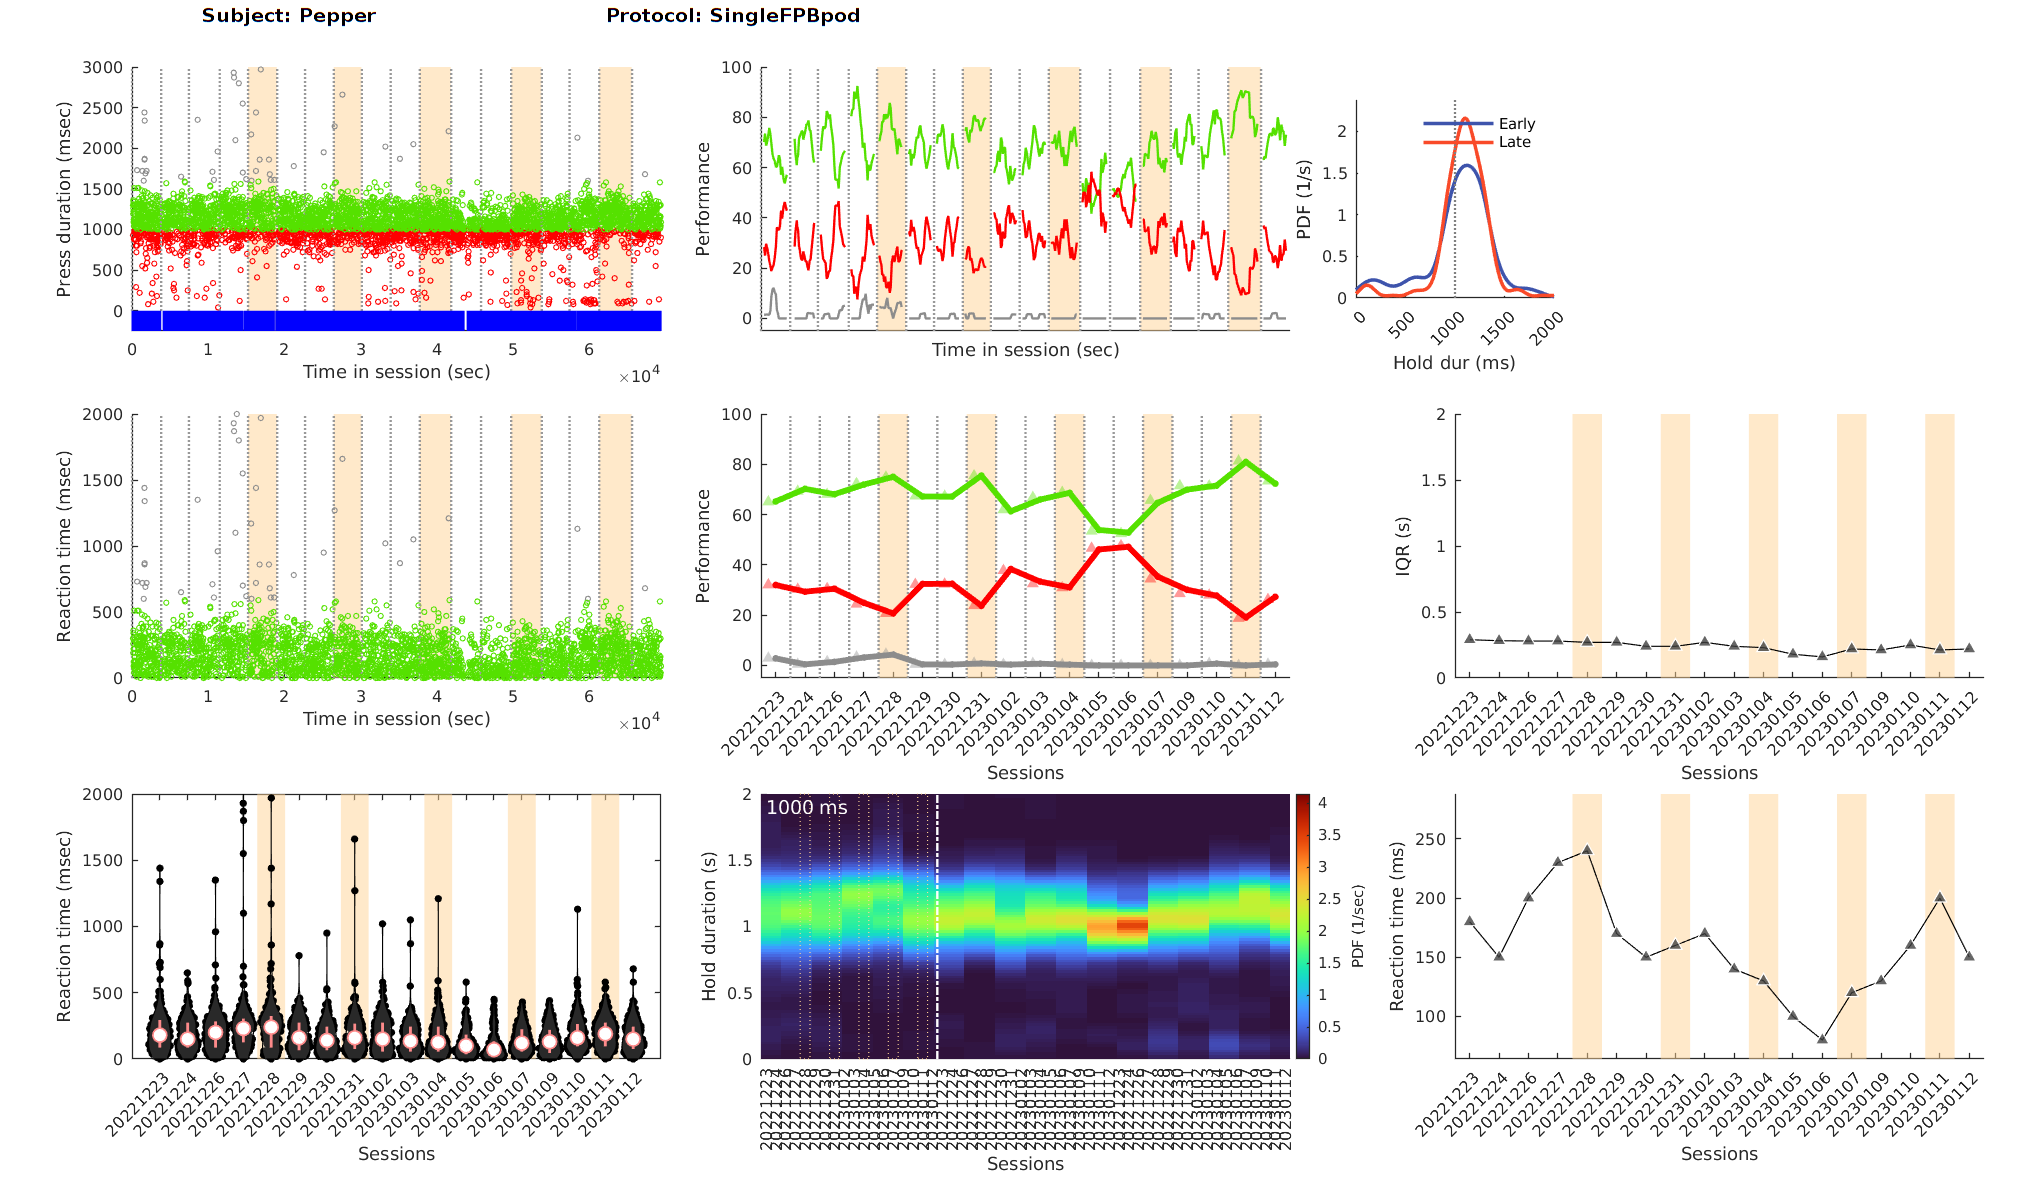

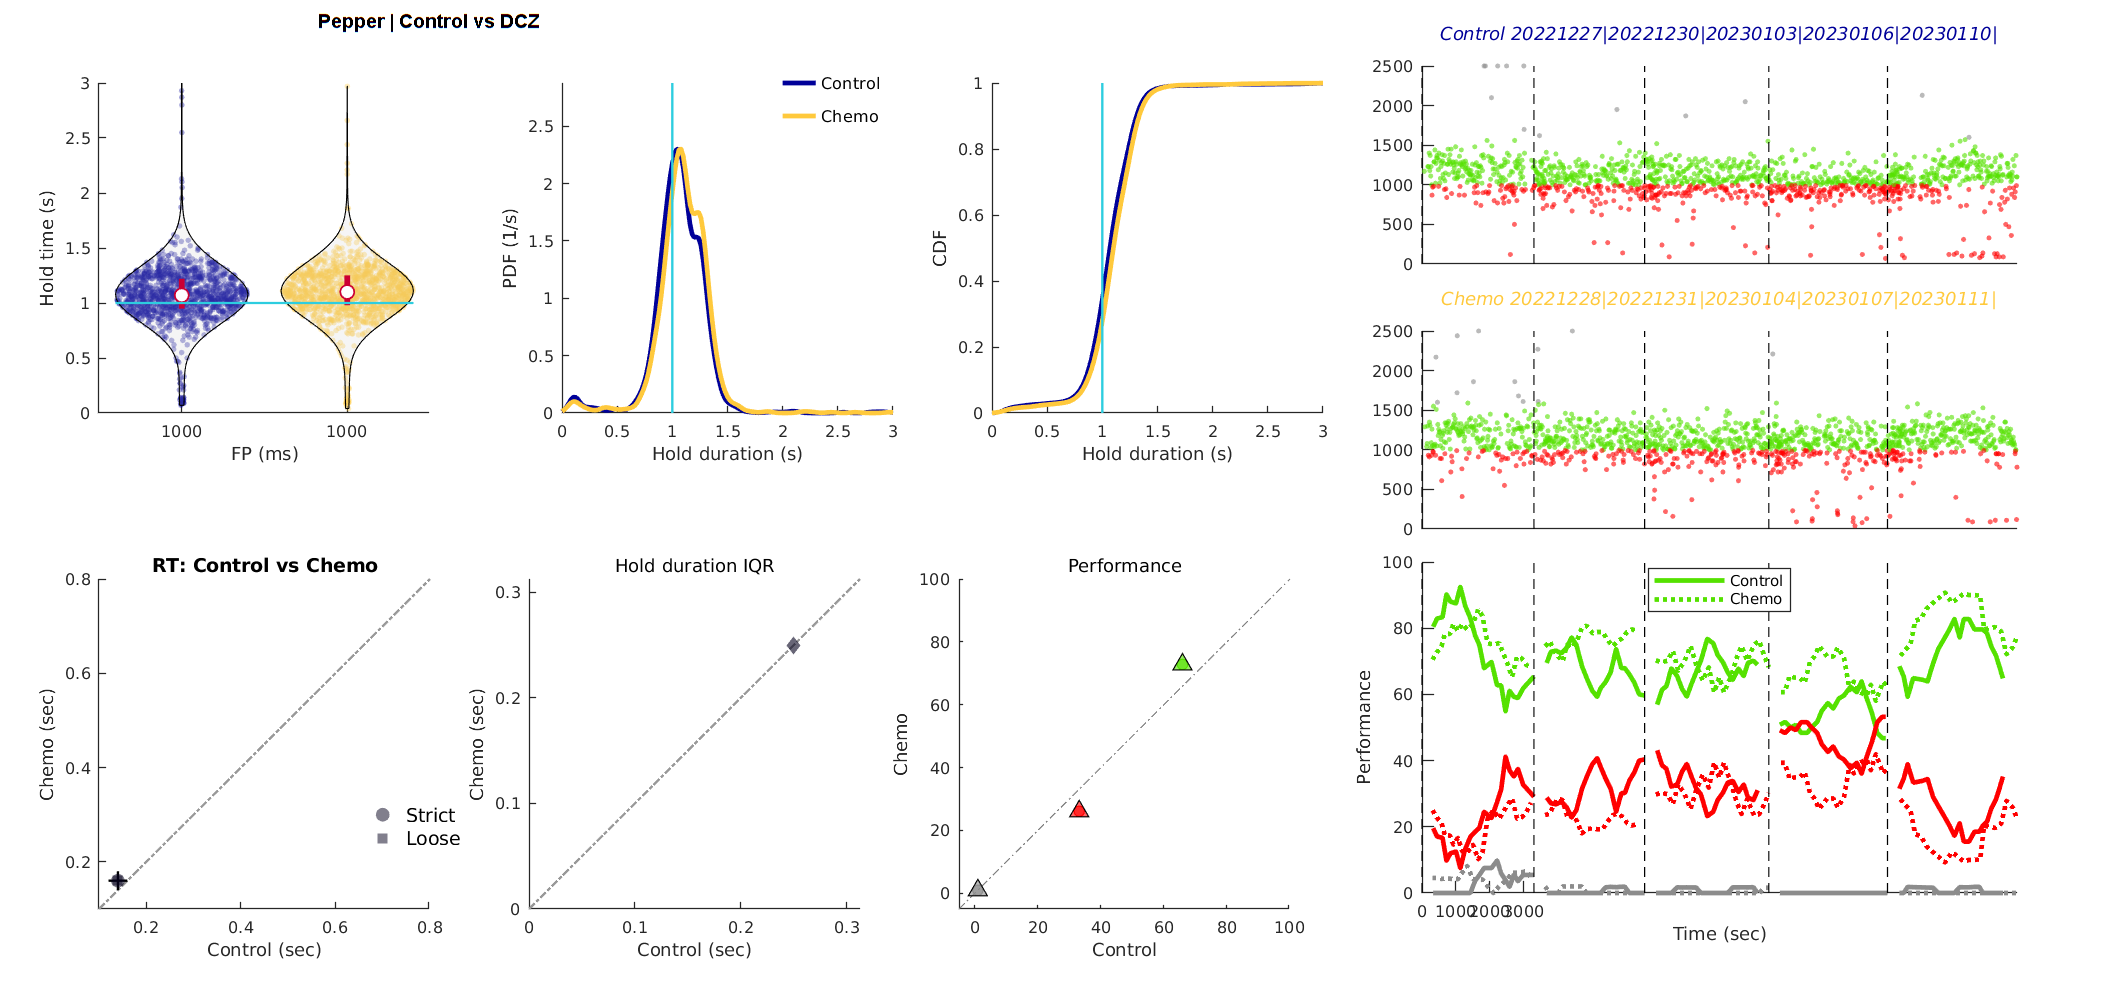

obj.Print();

obj.Save();